# 離散空間での経路計画

## A*アルゴリズム

function cm = CostMap(obstacles, field_size)
    % grid_size: [w, h]
    cm.obstacle_position = obstacles;
    cm.w = field_size(1);
    cm.h = field_size(2);
    cm.map_matrix = zeros(cm.w + 1, cm.h + 1);
    for k = 1:size(obstacles, 1)
        x = obstacles(k, 1);
        y = obstacles(k, 2);
        cm.map_matrix(x+1, y+1) = 1;
    end
end

function node = make_node(parent_idx, pose, g, h, f)
    node.parent = parent_idx; % 親ノードのインデックス（0 は None）
    node.pose = pose; % [x, y, theta]
    node.g = g;
    node.h = h;
    node.f = f;
end

function path = astar(start_pose, end_pose, cm, tolerance)
    if nargin < 4 
        tolerance = 0.1; 
    end
    
    % ノードは配列で保持し、親はインデックスで参照
    nodes = repmat(make_node(0, [0 0 0], 0, 0, 0), 0, 1); 
    nodes(1) = make_node(0, start_pose, 0, 0, 0);
    open   = 1; % オープンリスト（ノード配列のインデックス）
    closed = []; % クローズドリスト
    
    count = 0;
    iter_max = 1000;
    while count < iter_max && ~isempty(open)
        % f が最小のノードを取り出し
        [~, imin] = min([nodes(open).f]);
        current_idx = open(imin);
        open(imin) = [];
        closed(end+1) = current_idx; 
        current_pose = nodes(current_idx).pose;
    
        % ゴール判定（Python と同じ誤差定義）
        err = abs(current_pose(1) - end_pose(1)) ...
                + abs(current_pose(2) - end_pose(2)) ...
                + (1 - cos((current_pose(3) - end_pose(3))*pi/4));
        if err <= tolerance
            % パス復元（親インデックスを辿る）
            idx = current_idx;
            path = [];
            while idx ~= 0
                path = [nodes(idx).pose; path]; 
                idx = nodes(idx).parent;
            end
            fprintf('最適経路は ['); fprintf('(%d,%d,%d) ', path.'); fprintf('] です．\n');
            return
        end
    
        % 子ノード生成
        next_poses = calc_next_poses(current_pose);
        children = [];
        for i = 1:size(next_poses,1)
            xy = next_poses(i,1:2);
            if eval_safety(cm, xy)
                children = [children; next_poses(i,:)]; 
            end
        end
    
        % 各子ノードで G, H, F を計算してオープンへ
        for i = 1:size(children,1)
            child_pose = children(i,:);
    
            % 既にクローズリストに同一 (x,y,theta) があればスキップ
            if any(arrayfun(@(idx) all(nodes(idx).pose == child_pose), closed))
                continue
            end
    
            G = nodes(current_idx).g + 1;
            H = abs(child_pose(1) - end_pose(1)) ...
                        + abs(child_pose(2) - end_pose(2)) ...
                        + (1 - cos((child_pose(3) - end_pose(3))*pi/4));
            F = G + H;
    
            % オープン中に同じ (x,y) を持ち，かつその g がより小さいものがあればスキップ
            worse_than_open = false;
            for ok = 1:numel(open)
                on = nodes(open(ok));
                if all(child_pose(1:2) == on.pose(1:2)) && (G > on.g)
                    worse_than_open = true; break
                end
            end
            if worse_than_open, continue, end
    
            % 追加
            nodes(end+1) = make_node(current_idx, child_pose, G, H, F);
            open(end+1)  = numel(nodes); 
        end
    
        count = count + 1;
    
        if count >= iter_max
            fprintf('最適経路は見つかりませんでした！（反復上限に到達）\n');
            path = [];
            return
        elseif isempty(open)
            fprintf('最適経路は見つかりませんでした！（オープンリストが空）\n');
            path = [];
            return
        end
    end
    % ループを抜けた場合
    fprintf('最適経路は見つかりませんでした．\n');
    path = [];
end

function next_poses = calc_next_poses(current_pose)
    theta = current_pose(3);

    %--------------- 119-138行を修正 -------------------------%
    switch theta
        case 0
            dirs = [ 1 -1 -1;  1  0  0;  1  1  1;-1  1 -1; -1  0  0; -1 -1  1];
        case 1
            dirs = [ 1  0 -1;  1  1  0;  0  1  1;-1  0 -1; -1 -1  0;  0 -1  1];
        case 2
            dirs = [ 1  1 -1;  0  1  0; -1  1  1;-1 -1 -1;  0 -1  0;  1 -1  1];
        case 3
            dirs = [ 0  1 -1; -1  1  0; -1  0  1;0 -1 -1;  1 -1  0;  1  0  1];
        case 4
            dirs = [-1  1 -1; -1  0  0; -1 -1  1;1 -1 -1;  1  0  0;  1  1  1];
        case -3
            dirs = [-1  0 -1; -1 -1  0;  0 -1  1;1  0 -1;  1  1  0;  0  1  1];
        case -2
            dirs = [-1 -1 -1;  0 -1  0;  1 -1  1; 1  1 -1;  0  1  0; -1  1  1];
        case -1
            dirs = [ 0 -1 -1;  1 -1  0;  1  0  1;0  1 -1; -1  1  0; -1  0  1];
    end
    %--------------- 119-138行を修正 -------------------------%

    next_poses = current_pose + dirs;
end

function safe = eval_safety(cm, xy)
    x = xy(1); 
    y = xy(2);
    if (x > cm.w) || (x < 0) || (y > cm.h) || (y < 0)
        safe = false; return
    end
    if cm.map_matrix(x+1, y+1) ~= 0
        safe = false; return
    end
    safe = true;
end

## 結果の表示

function plot_result(cm, start, goal, path)
    cells = cm.obstacle_position;
    xmin = -0.5; 
    xmax = cm.w + 0.5;
    ymin = -0.5; 
    ymax = cm.h + 0.5;
    
    figure; ax = gca; hold(ax,'on');
    
    % 障害セル（黒）
    for k = 1:size(cells,1)
        x = cells(k,1); 
        y = cells(k,2);
        rectangle('Position',[x-0.5, y-0.5, 1, 1], 'FaceColor','k', 'EdgeColor','k', 'LineWidth',1);
    end
    
    % 経路（三角形）
    if ~isempty(path) 
        for k = 1:size(path,1)
            draw_thin_triangle(ax, path(k,:));
        end
    end
    
    % 始点・終点枠
    rectangle('Position',[start(1)+0.03-0.5, start(2)+0.03-0.5, 0.95, 0.95], ...
              'EdgeColor',[0 0.6 0], 'LineWidth', 3, 'FaceColor','none');
    rectangle('Position',[goal(1)+0.03-0.5, goal(2)+0.03-0.5, 0.95, 0.95], ...
              'EdgeColor',[0.85 0 0], 'LineWidth', 3, 'FaceColor','none');
    
    % 軸設定
    axis equal; 
    box on;
    xlim([xmin xmax]); 
    ylim([ymin ymax]);
    xticks(0:cm.w)
    yticks(0:cm.h)

    grid on;
    xlabel('x','FontSize', 16); 
    ylabel('y','FontSize', 16);   
    fontsize(16, "points")
    hold(ax,'off');
end

function draw_thin_triangle(ax, pose, len, wid, face, edge, alphaVal)
    if nargin < 3, len = 0.7; end
    if nargin < 4, wid = 0.5; end
    if nargin < 5, face = [30 144 255]/255; end 
    if nargin < 6, edge = [0 0 0.5]; end       
    if nargin < 7, alphaVal = 0.9; end
    
    x = pose(1); 
    y = pose(2); 
    theta = pose(3);
    ang = double(theta)*pi/4;
    
    pts = [ x + len/2, y;          % 先端
            x - len/2, y + wid/2;  % 基部上
            x - len/2, y - wid/2]; % 基部下
    
    % 中心 (x, y) 回りに回転
    R = [cos(ang) -sin(ang); sin(ang) cos(ang)];
    p0 = pts - [x y];
    pR = (R * p0.').';
    pR = pR + [x y];
    
    patch('XData',pR(:,1),'YData',pR(:,2), ...
          'FaceColor',face,'EdgeColor',edge,'FaceAlpha',alphaVal, ...
          'Parent',ax);
end

## 実行

field_size = [4, 4];   % [w, h]
start     = [0, 0, 2]; % [x, y, theta]
goal      = [4, 4, 4]; % [x, y, theta]
tolerance   = 0.1;   % ゴール判定誤差

% 障害物があるグリッド
obstacles = [1 3; 2 1; 2 3; 3 0; 3 1]; 

% マップの生成
cost_map = CostMap(obstacles, field_size);
disp("障害物一覧（[x y]）:");

障害物一覧（[x y]）:


disp(cost_map.obstacle_position);

     1     3
     2     1
     2     3
     3     0
     3     1




% 経路計画
path = astar(start, goal, cost_map, tolerance);

最適経路は [(0,0,2) (1,1,1) (2,2,1) (3,3,1) (3,4,2) (3,3,2) (2,4,3) (3,4,4) (4,4,4) ] です．


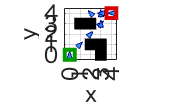


% 結果の表示
plot_result(cost_map, start, goal, path);